% Sample data
reactivity_amblyopia = [0.5, 0.6, 0.7, 0.4, 0.3];
reactivity_control = [0.2, 0.1, 0.3, 0.4, 0.3];

% Descriptive Statistics
stats_amblyopia = struct();
stats_amblyopia.mean = mean(reactivity_amblyopia);
stats_amblyopia.std = std(reactivity_amblyopia);
stats_amblyopia.median = median(reactivity_amblyopia);
stats_amblyopia.iqr = iqr(reactivity_amblyopia);
stats_amblyopia.min = min(reactivity_amblyopia);
stats_amblyopia.max = max(reactivity_amblyopia);

stats_control = struct();
stats_control.mean = mean(reactivity_control);
stats_control.std = std(reactivity_control);
stats_control.median = median(reactivity_control);
stats_control.iqr = iqr(reactivity_control);
stats_control.min = min(reactivity_control);
stats_control.max = max(reactivity_control);

% Display Descriptive Statistics
disp('Descriptive Statistics for Amblyopia Group:');

Descriptive Statistics for Amblyopia Group:


disp(stats_amblyopia);

      mean: 0.5000
       std: 0.1581
    median: 0.5000
       iqr: 0.2500
       min: 0.3000
       max: 0.7000




disp('Descriptive Statistics for Control Group:');

Descriptive Statistics for Control Group:


disp(stats_control);

      mean: 0.2600
       std: 0.1140
    median: 0.3000
       iqr: 0.1500
       min: 0.1000
       max: 0.4000




% Normality Test
[hAmblyopia, pAmblyopiaNorm] = adtest(reactivity_amblyopia);
[hControl, pControlNorm] = adtest(reactivity_control);

fprintf('Normality Test for Amblyopia Group: p-value = %.4f\n', pAmblyopiaNorm);

Normality Test for Amblyopia Group: p-value = 0.9896


fprintf('Normality Test for Control Group: p-value = %.4f\n', pControlNorm);

Normality Test for Control Group: p-value = 0.7262


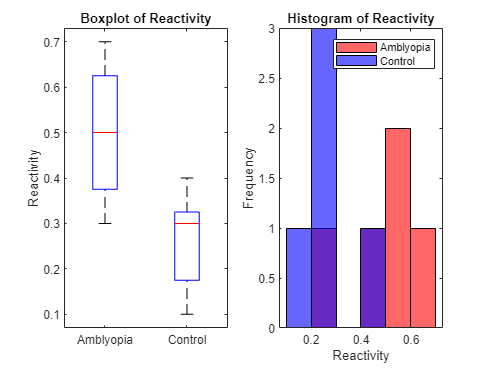


% Create Boxplot
figure;
subplot(1, 2, 1);
boxplot([reactivity_amblyopia', reactivity_control'], 'Labels', {'Amblyopia', 'Control'});
title('Boxplot of Reactivity');
ylabel('Reactivity');

% Create Histogram
subplot(1, 2, 2);
histogram(reactivity_amblyopia, 'FaceColor', 'r', 'EdgeColor', 'k', 'BinWidth', 0.1);
hold on;
histogram(reactivity_control, 'FaceColor', 'b', 'EdgeColor', 'k', 'BinWidth', 0.1);
hold off;
title('Histogram of Reactivity');
xlabel('Reactivity');
ylabel('Frequency');
legend({'Amblyopia', 'Control'});


% Single-group t-test
[hAmblyopia, pAmblyopiaTTest] = ttest(reactivity_amblyopia, 0.5);
[hControl, pControlTTest] = ttest(reactivity_control, 0.5);

% Display t-test results for each group
fprintf('Single-group t-test for Amblyopia Group: p-value = %.4f\n', pAmblyopiaTTest);

Single-group t-test for Amblyopia Group: p-value = 1.0000


fprintf('Single-group t-test for Control Group: p-value = %.4f\n', pControlTTest);

Single-group t-test for Control Group: p-value = 0.0093



% Two-sample t-test
[h, pGroup] = ttest2(reactivity_amblyopia, reactivity_control);

% Display t-test results for group comparison
fprintf('Two-sample t-test: p-value = %.4f\n', pGroup);

Two-sample t-test: p-value = 0.0249


if pGroup < 0.05
    fprintf('Significant difference between amblyopia and control groups.\n');
else
    fprintf('No significant difference between amblyopia and control groups.\n');
end

Significant difference between amblyopia and control groups.
